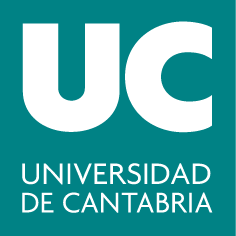

#### ***Grado en Ingeniería Química***

## **G320: Álgebra**

# **Práctica 3: Variables simbólicas**

*Rodrigo García Manzanas (rodrigo.manzanas@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es)*

**Uso de variables simbólicas en MATLAB**

MATLAB permite trabajar con variables simbólicas, es decir, variables genéricas que, en principio, no tienen por qué tomar un valor concreto.

syms x  % defino la variable 'x' como simbólica
ex = x^2 + 5  % expresión que depende de 'x'

Por depender de la variable simbólica *x, ex *será una expresión simbólica. Podemos comprobar de qué tipo es una variable dada con el comando *class*:

class(x)  % 'x' es una variable simbólica
class(ex)  % 'eq' es una expresión simbólica

Podemos obligar a que una variable simbólica tome un determinado valor con el comando *subs*:

subs(ex, x, 3)  % forzamos a que 'x' tome el valor 3 en la expresión eq

Se pueden definir varias variables simbólicas a la vez:

syms x y
subs(2*x + y, [x, y], [1 6])  % forzamos a que 'x' ('y') tome el valor 1 (6) 
% en la expresión '2*x+y'

Se puede especificar el tipo exacto de variable simbólica con la que queremos trabajar:

syms x integer  % 'x' sólo podría tomar valores enteros
syms x real  % 'x' podría tomar cualquier valor real

En esta asignatura trabajaremos siempre con variables simbólicas de tipo *real*.

Por último veremos el comando *solve*, que permite resolver ecuaciones (de hecho, sistemas de ecuaciones). De momento consideraremos sólo ecuaciones sencillas de una incógnita. La igualdad en una ecuación simbólica se denota con el símbolo "==":

syms x real
sol = solve(7 + x == 2, x)  % devuelve el valor de 'x' que cumple la 
% ecuación '7+x=2'

Fíjate que la variable *sol *es simbólica. Para convertirla a tipo numérico hay que utilizar el comando *double:*

class(sol)  % variable de tipo simbólico
class(double(sol))  % variable de tipo numérico

Si prescindimos del "==*"*, el comando *solve *considera la expresión que le pasemos como una ecuación y la iguala a $0$. Por tanto, las siguientes dos órdenes son equivalentes en MATLAB:

sol1 = solve(6 + 2*x == 0, x)  % devuelve el valor de 'x' que cumple la 
% ecuación '6+2x=0'
sol2 = solve(6 + 2*x, x)  % devuelve el valor de 'x' que cumple la 
% ecuación '6+2x=0'

**Nota importante**: Las funciones *inv*, *rref *y* rank* pueden dar lugar a resultados incorrectos cuando actúan sobre matrices simbólicas, por lo que restringiremos su uso únicamente a matrices numéricas. Por contra, la función *det* puede utilizarse sin riesgo en cualquier caso, tanto con matrices numéricas como con matrices simbólicas.

#### Ejercicios propuestos

**Ejercicio 1: **

Determina para qué valores del parámetro $a$ es ortogonal la matriz $A$. Comprueba tus resultados.


$$A=\left\lbrack \begin{array}{ccc}
0\ldotp 8 & a & 0\\
-a & 0\ldotp 8 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


**Ejercicio 2: **

Determina el rango de $A$ en función del parámetro $a$. Comprueba tus resultados.


$$A=\left\lbrack \begin{array}{cccc}
2 & 2a & 5 & 3\\
7 & -2 & 4 & -3\\
9 & 7 & 1 & -a\\
1 & 7 & 0 & -2
\end{array}\right\rbrack$$


**Ejercicio 3:**

Sea la matriz $A=\left\lbrack \begin{array}{ccc}
1 & -1 & 2\\
a & 0 & 1\\
2 & a & -2
\end{array}\right\rbrack$. Determina si es o no regular (es decir, invertible), en función del parámetro $a$. Comprueba tus resultados.